% Момент - Михаил
%  Обработка момента

addpath(genpath('E:\Motorcycle\Models\MatLab'))

PathsDan = 'E:\Motorcycle\Data\MatLab\Mixail';
NameFile = 'Mixa.mat'
PathFile = PathsDan+"\"+NameFile
load('-mat', PathFile)


momentBasa = Mixa.Moment(600:length(Mixa.Moment));
nPointTest =  9500 %length(Mixa.Moment)

nPointTest = 9500

tmomentBasa = momentBasa(1:nPointTest);
dMoment0 = zeros(1, nPointTest);
dMoment = zeros(1, nPointTest);
dacc0 = zeros(1, nPointTest);
dacc = zeros(1, nPointTest);
t0=[0:nPointTest-1];

nsd=25

nsd = 25

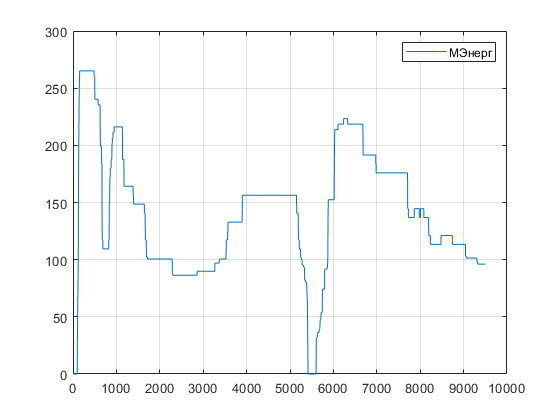

dMoment0(1, nsd:nPointTest-1)=tmomentBasa(1, 1:nPointTest-nsd);
dMoment =tmomentBasa- dMoment0;
dacc0(1, nsd:nPointTest-1)=dMoment(1, 1:nPointTest-nsd);
dacc = dMoment - dacc0;

figure
plot(t0, tmomentBasa)
grid()
legend('MЭнерг')

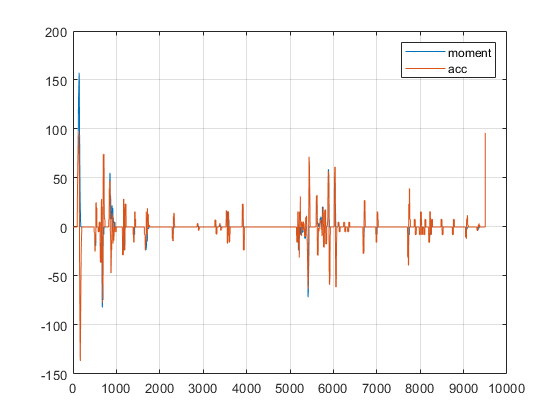


figure
plot(t0, dMoment, t0, dacc)
grid()
legend('moment', 'acc')

nPointTest = 9000

nReg = 50

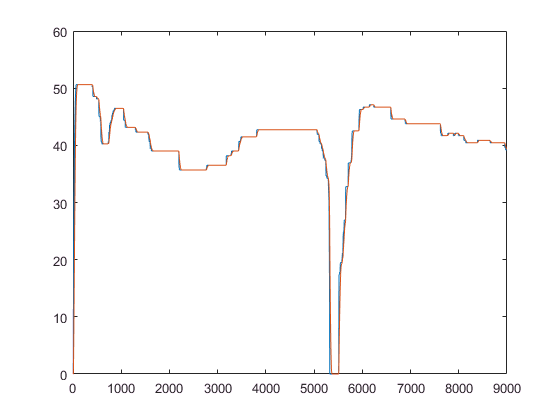

ema0 = 0

alfa = 0.2500

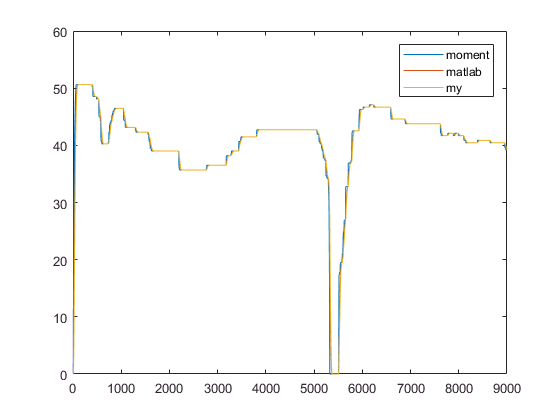


figure

plot(t0, d(1,:))
legend('moment','my')
%plot(t0, d0)


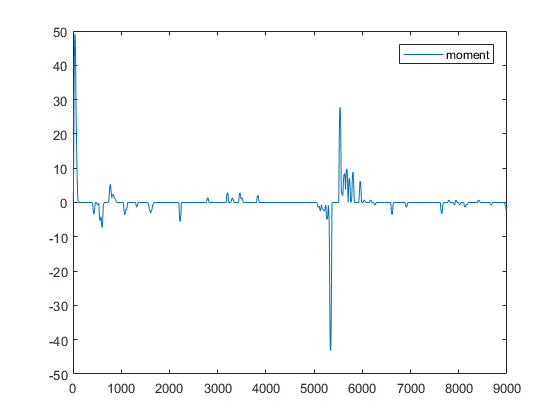


NCount = 13;
m = zeros(1,200);        
nm = 200;            

n=13

x = [0:step:(n-1)*step]
x0 = zeros(1, n)
x0(1,:)=[0:step:(n-1)*step]
xsum = sum(x0(1,1:n))
x2sum = sum(x0.^2)
x_sr = xsum / n
x_0 = x -x_sr
x_01 = sum(x_0.^2)
x_001 = 1/x_01
xsum2 = xsum * xsum
z0 = x2sum / xsum2
z01 = 1 / (1 - (z0 * n))
z002 = 1 / xsum

for i = 1:n
    m(1, 2:nm) = m(1, 1:nm-1);
    m(1,1) = double(y11(n-i+1));
end

yy(:) = m(1, 1:n)

mdl1 = fitlm(x0, yy)
count = length(mdl1.Fitted)
z = mdl1.Fitted(count)


ysum = sum(yy)
y2sum = sum(yy.^2)
xy = x0.*yy
xysum = sum(xy)
y_sr = ysum / n
y_0 = yy-y_sr
su = sum(x_0.* y_0)
b = su*x_001
z1 = xysum*z002
betta = (z1-z0*ysum)*z01
alfa = (ysum - betta * n) * z002
ugol =  atan(alfa) * 180 / pi
zzzz = alfa*((n-1)*step)+betta

%         betta = (_z1 - self.kX[str(_xcount)]["_z0"] * ysum) * self.kX[str(_xcount)]["_z01"]     # смещение по X
%         alfa = (ysum - betta * _xcount) * self.kX[str(_xcount)]["_z002"]                        # угол наклона
%         _ugol = np.arctan(alfa) * 180 / np.pi                                                   # угол наклона в градусах
% 
%         __y = list(map(lambda _q: alfa *_q + betta, _x))
% 
%         __z = np.array(list(map(lambda _y0, _y1: _y0-_y1, _y, __y)))
%         # Для оценки качества модели используется критерий суммы квадратов регрессионных остатков, SSE — Sum of Squared Errors.
%         sse = np.dot( __z.transpose(),  __z )
% 
%         # Найдем выборочный коэффициент корреляции: чем ближе к 1 тем лучше
%         __koef_cor = (_xcount * xysum - self.kX[str(_xcount)]["xsum"] *ysum)/\
%                      (np.sqrt(_xcount * self.kX[str(_xcount)]["x2sum"] - self.kX[str(_xcount)]["xsum2"]) * np.sqrt(_xcount * y2sum -ysum*ysum))
% 
% 





x11 = [10, 14, 21, 23, 27, 32, 39, 45, 55, 61, 62, 68, 70]
y11 = [3.8, 4.8, 5.9, 6.1, 6.2, 6.3, 6.6, 7.4, 8.5, 9.7, 10.5, 12.4, 12.1]

mdl = fitlm(x11, y11)
count = length(mdl.Fitted)
z = mdl.Fitted(count)
%mdl = fitlm(tbl,'ResponseVar','BloodPressure');


line_reg = LineRegres();
count = line_reg.GetCount();

ww = round(51/3)

ww = 17


n = 20

n = 20

m = zeros(1,20)

m =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


m(2) = 9

m =      0     9     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


m(20) = 1

m =      0     9     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1


m(1:n-1) = m(2:n)

m =      9     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1


m( 20)=2

m =      9     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     2


y=m(n-5: n)

y =      0     0     0     0     1     2


y11 = [3.8, 4.8, 5.9, 6.1, 6.2, 6.3, 6.6, 7.4, 8.5, 9.7, 10.5, 12.4, 12.1];
y10 = [0, 0, 0, 0, 0, 0, 0, 0, 0, 0,  0,  0, 0];
x10 = [0, 1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11, 12];
n=13;
for i=1:n
    i
    y_yy = y11(i);
    y10(1:n-1) = y10(2:n);
    y10(n)=y_yy;
    mdl = fitlm(x10, y10);
    z = mdl.Fitted(n)
    z1 = line_reg.CalcStep(n, y_yy)    
end

% mdl = fitlm(x11, y11)
% count = length(mdl.Fitted)
% z = mdl.Fitted(count)
% %mdl = fitlm(tbl,'ResponseVar','BloodPressure');
